# Sessió 10

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');
yfit = trainedModel.predictFcn(fishertable);


## 2. Classificació automàtica d’espècies arbòries

Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier. Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i quines no són significatives.

Al trabajar con los descriptores de Fourier de las respectivas imagenes, se nos planteó el dilema de usar el modulo de los descriptores odividir los descriptores, que son números complejos, en dos partes, real e imaginaria.

Haremos pruebas de ambos casos y decidiremos cual nos dá un mejor resultado.

## Clasificación 

Primero estudiaremos los resultado en función del número de descriptores (5, 20 , 50 ,75)

Para las pruebas, hemos decidido dividir nuestros datos en 2 conjuntos: Train y Test.

Test es un 30% del total de los datos y serán escogidos aleatoriamente en cada prueba, sin embargo, sabremos que del 30%, el primer tercio son Arce, el segundo tercio son Haya y el último tercio son Roble.

### Clasificación usando parte real e imaginaria

- Usando 5 descriptores nos da los siguientes resultados:

            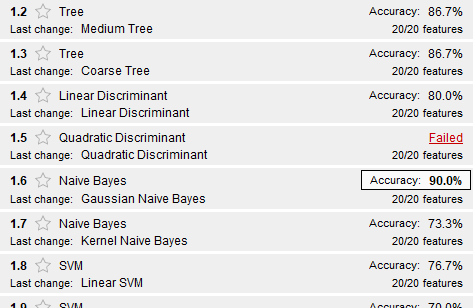

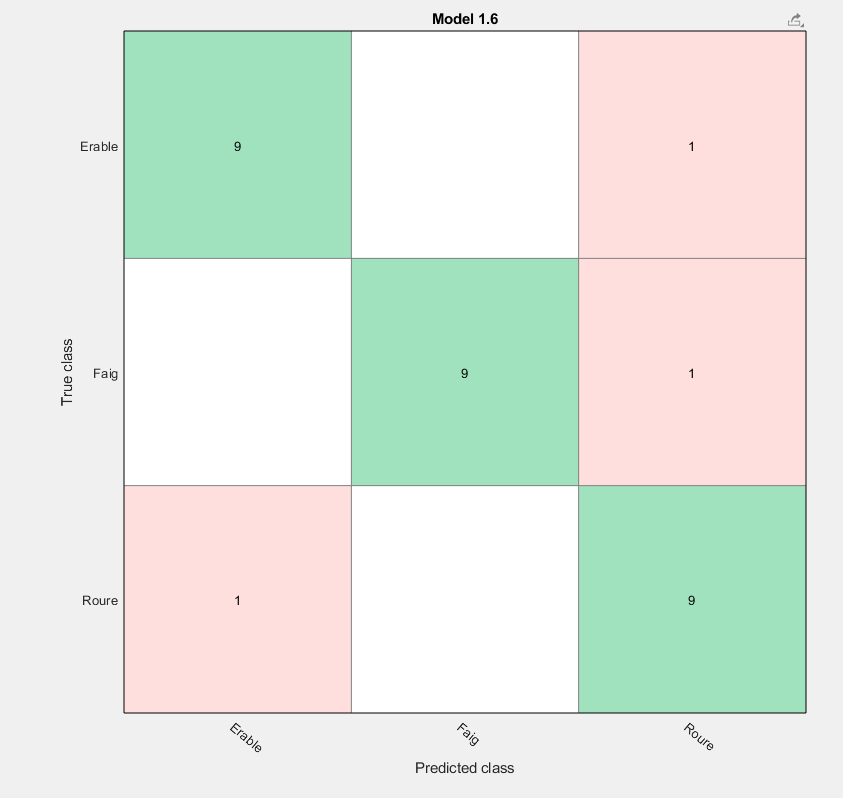

Haremos una prueba con los datos Test:

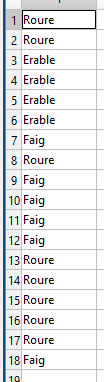

Como se puede observar y sabiendo los resultados correctos expuestos arriba, hay un gran porcentaje de fallos, un 20% aproximadamente. 

- Usando 20 descriptores nos da los siguientes resultados:

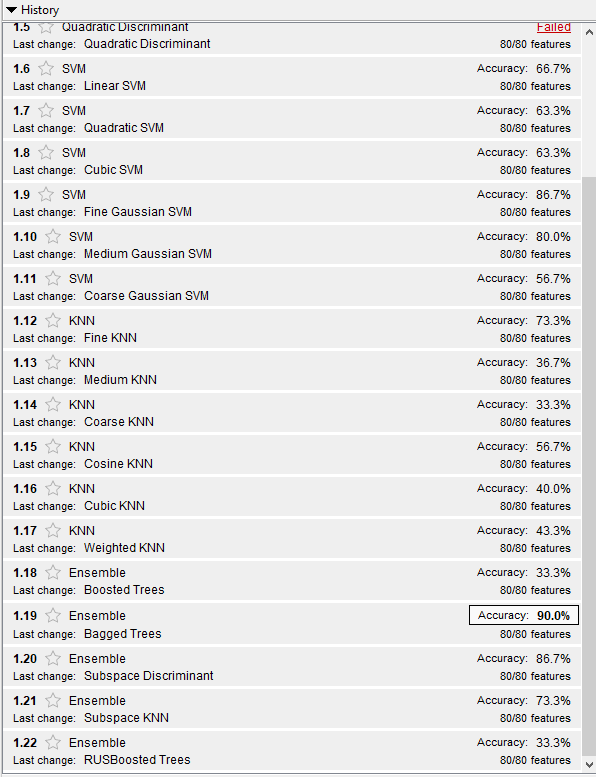

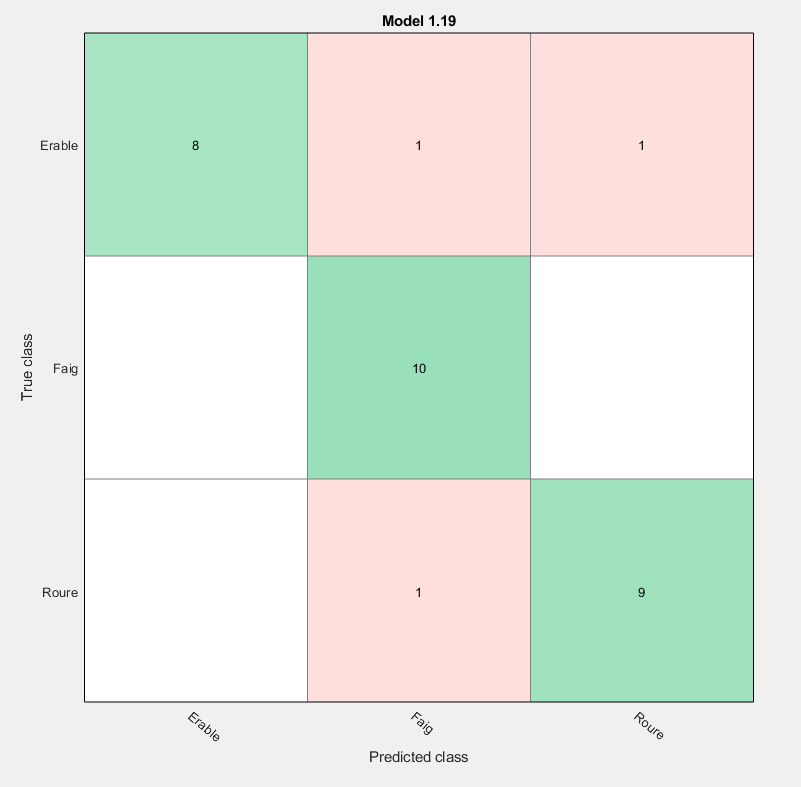

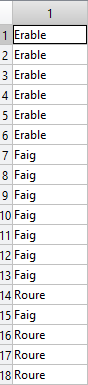

Como podemos observar solo ha fallado 2/18. Lo que demuestra que ha disminuido bastante el error.

- Usando 50 descriptores nos da los siguientes resultados:

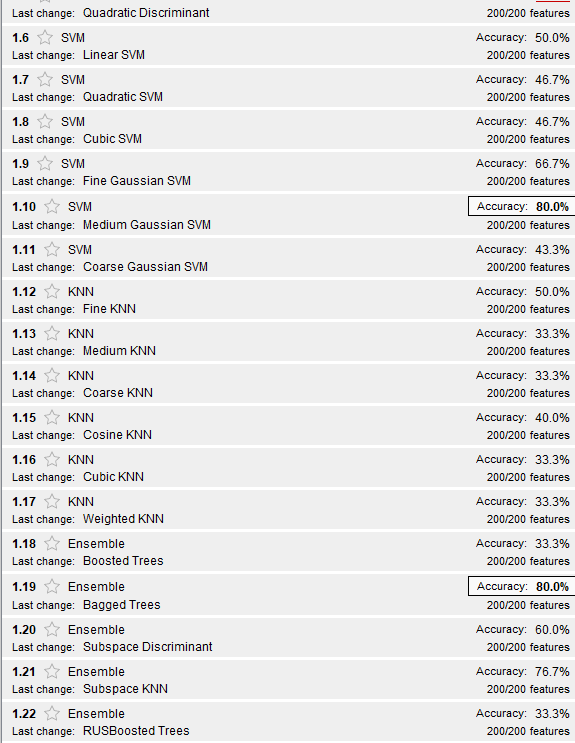

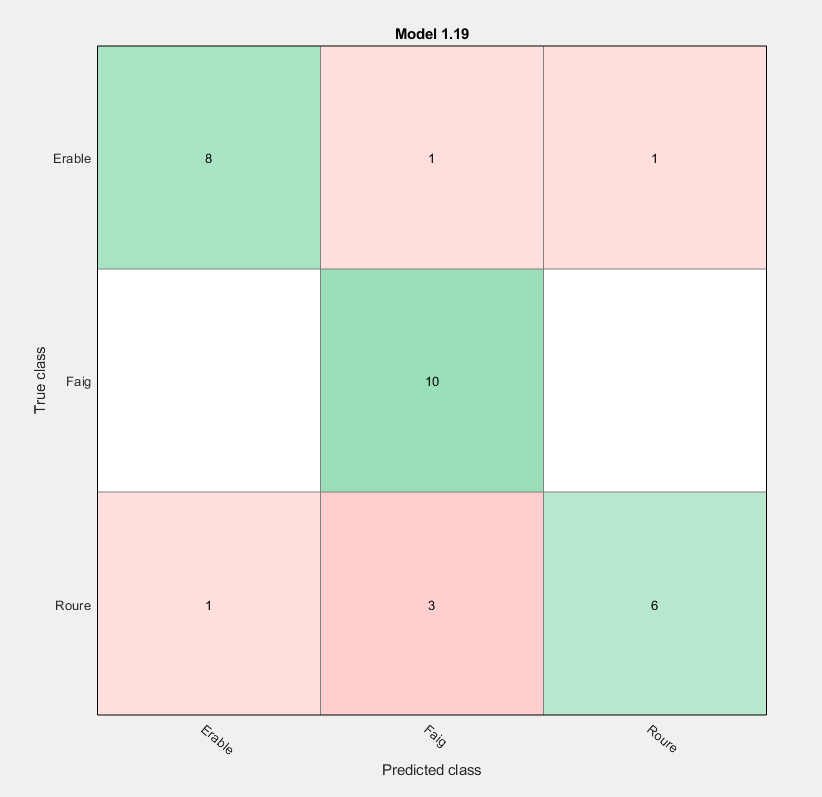

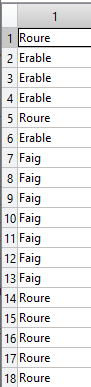

Como podemos observar ha fallado en 3/16. Como se puede admirar los resultados han empeorado respecto a los anteriores experimentos.

- Usando 75 descriptores nos da los siguientes resultados:

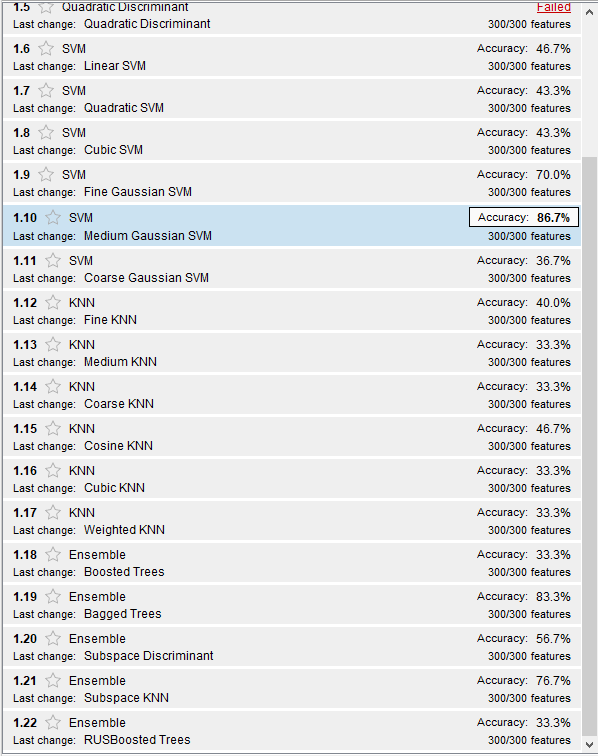

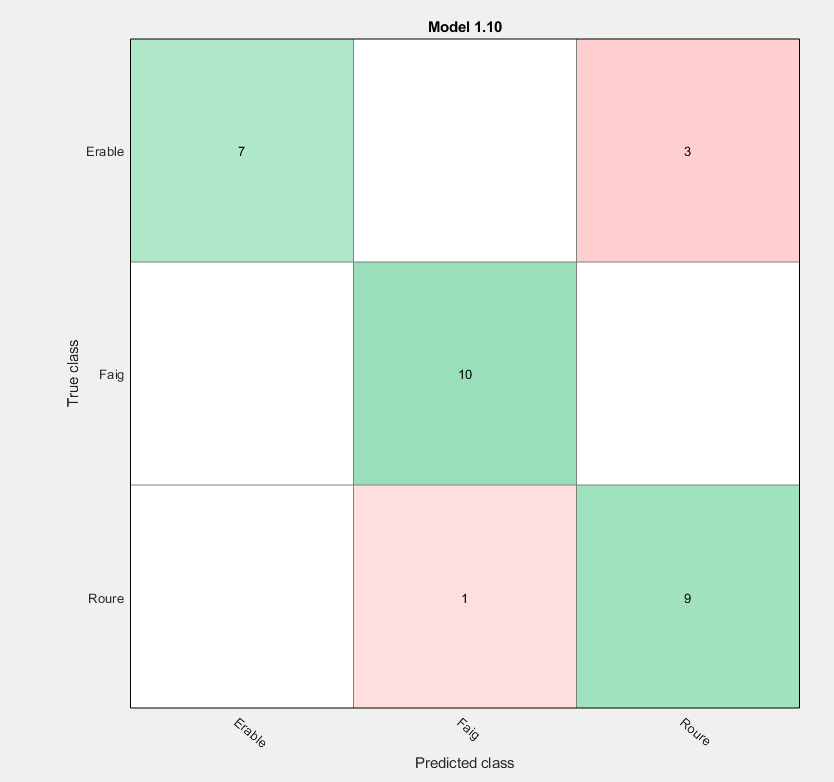

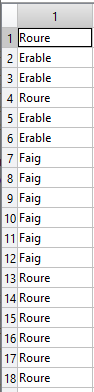

Como podemos observar ha fallado en 2/16. Como se puede admirar los resultados han mejorado pero no son superior a los que han dado con 5 y 20 descriptores.

- Usando 5 descriptores nos da los siguientes resultados:

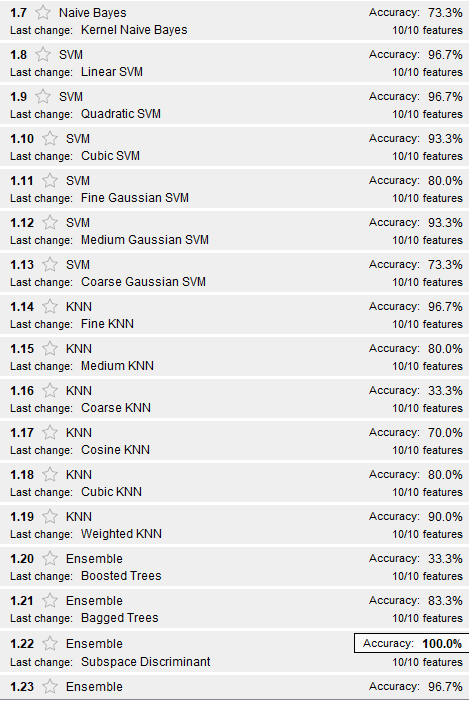

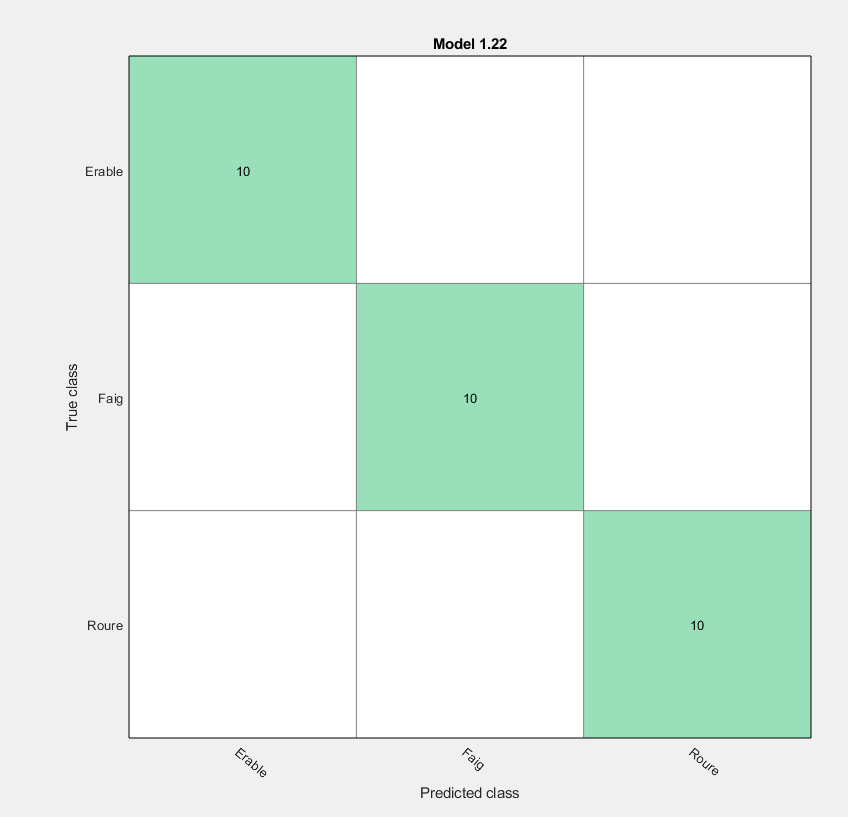

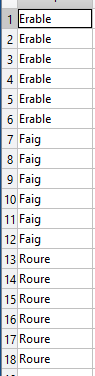

Buenos resultados aunque es posible debido a la poca cantidad de datos

- Usando 20 descriptores nos da los siguientes resultados:

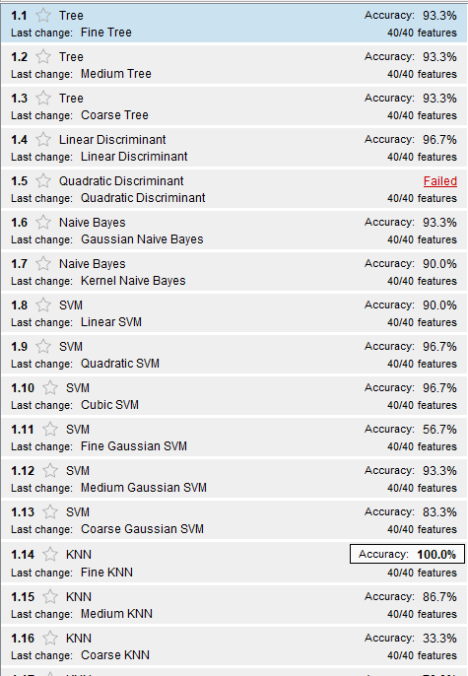

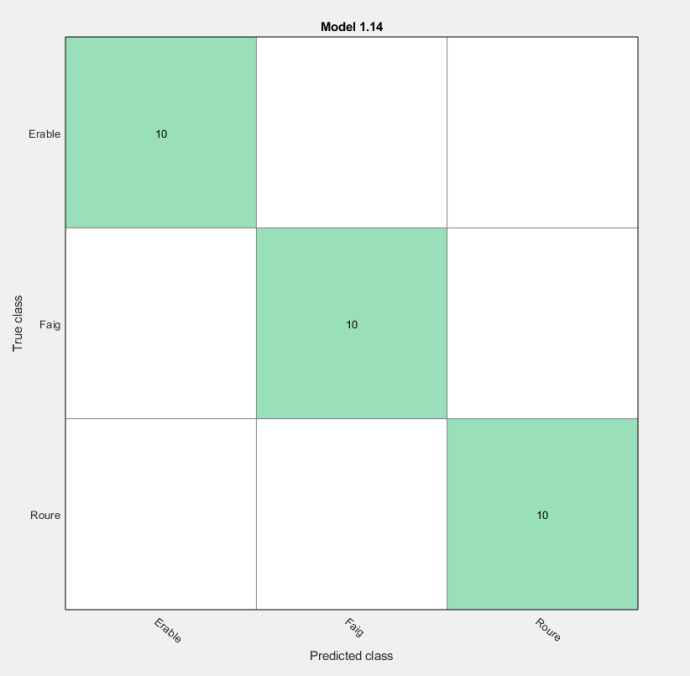

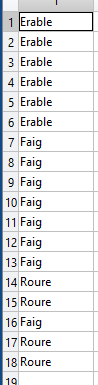

En este experimento podemos ver que hay un clasificador que funciona con 100% de exito. En contraposición ha fallado 2 veces. 

- Usando 50 descriptores nos da los siguientes resultados:

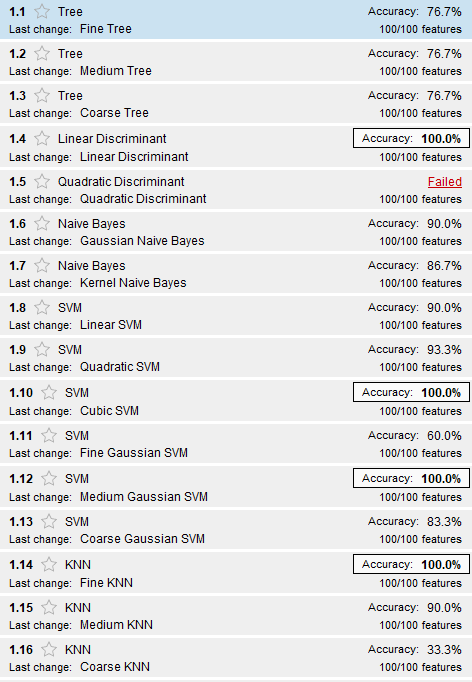

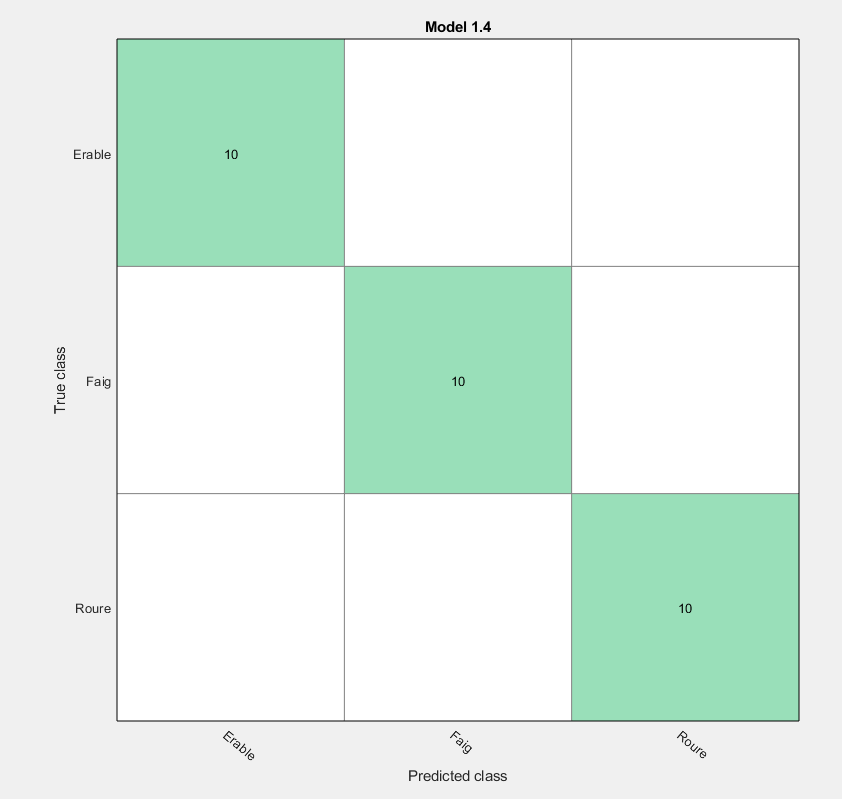

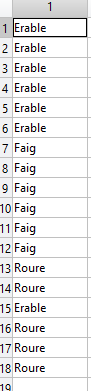

Como podemos observar con 50 descriptores hay un clasificador que nos sale con 100 % de error. En contraposición al usar los test nos sale que se equivoca una vez

- Usando 75 descriptores nos da los siguientes resultados:

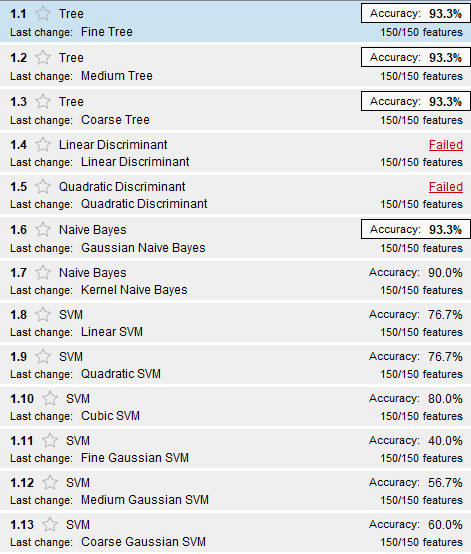

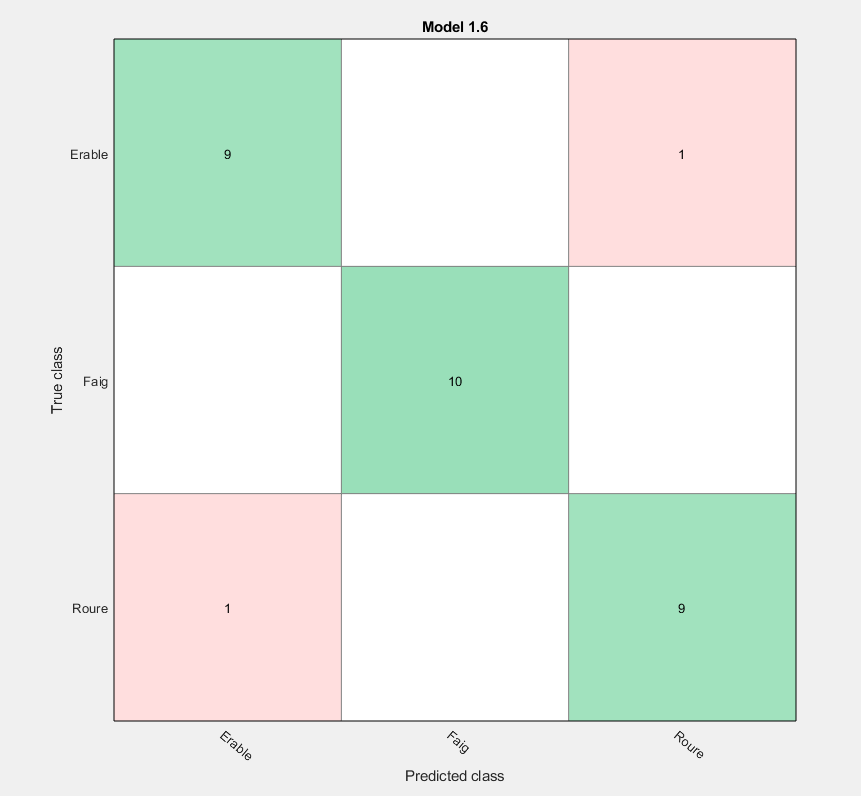

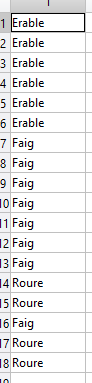

Como podemos observar a partir de 75 empieza a fallar el algoritmo. Probablemente se deba a que utilizamos demasiados descriptores.

**Conclusiones**

Como conclusión diriamos que el numero de descriptores es un factor importante para crear un clasificador. El hecho de coger poco hace que el clasificador no tenga demasiado features para estudiar en contraposición si cogemos más de 50 features los modelos que salian despues de entrenar un clasificador fallaban. También es importante ver que features se puede extraer para hacer un buen clasificador. Como hemos podido ver en la mayoria de clasificadores cuyo features era el valor absoluto de la transformación de fourier daban buenos resultados.

%im = imread('l2nr002.jpg')
%[descriptor] = descriptor_fourier(im,nan)
p = randperm(16);
train = p(1:10);
test = p(11:16);
[T1Train, T2Train, dataTrain] = getdataexercise2(train)

data =     3.8587    7.0293    7.6136    7.5930    7.1094    7.4845    4.9829    6.2418    5.6200    5.5725    5.0752    6.2347    5.0658    6.6293    5.4352    2.6575    4.7929    5.6931    5.5504    3.4389    5.0569    4.8682    4.5990    4.8705    3.6438    4.5592    5.1833    5.0728    4.7438    4.0690    4.0330    4.2934    4.1888    4.6984    4.3614    3.5976    4.3362    4.3104    3.8780    4.6780    2.6001    2.7394    4.4769    3.4087    3.1349    3.7453    2.8253    3.0926    3.4676    2.0799
  -27.1308    7.4173    6.5639    6.5329    7.1705    6.4775    5.7044    6.1339    5.8082    5.0561    6.0168    5.3235    5.6249    6.3498    6.0891    4.9910    5.4814    5.5042    5.4903    5.6352    5.1537    5.4901    5.4398    4.8570    5.1554    4.5391    3.0320    4.3869    4.5969    4.2744    4.4525    4.1347    4.7890    3.7021    4.1367    4.5444    3.9613    2.6605    3.7814    2.7678    4.3748    3.3972    3.7642    4.2261    3.7172    3.8551    3.3795    3.9892    4.2441  

T1Train = 30×2 table
         Var1         namesleaf
    ______________    _________

    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   


T2Train = 30×2 table
         Var1         namesleaf
    ______________    _________

    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   


dataTrain =     3.8587    7.0293    7.6136    7.5930    7.1094    7.4845    4.9829    6.2418    5.6200    5.5725    5.0752    6.2347    5.0658    6.6293    5.4352    2.6575    4.7929    5.6931    5.5504    3.4389    5.0569    4.8682    4.5990    4.8705    3.6438    4.5592    5.1833    5.0728    4.7438    4.0690    4.0330    4.2934    4.1888    4.6984    4.3614    3.5976    4.3362    4.3104    3.8780    4.6780    2.6001    2.7394    4.4769    3.4087    3.1349    3.7453    2.8253    3.0926    3.4676    2.0799
  -27.1308    7.4173    6.5639    6.5329    7.1705    6.4775    5.7044    6.1339    5.8082    5.0561    6.0168    5.3235    5.6249    6.3498    6.0891    4.9910    5.4814    5.5042    5.4903    5.6352    5.1537    5.4901    5.4398    4.8570    5.1554    4.5391    3.0320    4.3869    4.5969    4.2744    4.4525    4.1347    4.7890    3.7021    4.1367    4.5444    3.9613    2.6605    3.7814    2.7678    4.3748    3.3972    3.7642    4.2261    3.7172    3.8551    3.3795    3.9892    4.2

[T1Test, T2Test, dataTest] = getdataexercise2(test)

data =   -27.3793    6.7368    6.4260    4.3216    6.5274    6.2917    4.9732    6.1190    5.1771    4.5162    4.4639    5.9595    5.4679    5.3043    3.2120    5.6779    5.2905    4.0601    3.9747    4.1283    4.5750    3.4149    4.4978    4.0096    4.1555    4.4784    2.2836    4.3577    2.9992    3.9377    2.5271    3.4461    3.3906    2.9735    3.2362    3.3846    3.7702    3.5138    2.5178    3.7036    2.2698    3.2536    2.8059    2.8434    3.2062    3.1549    2.9857    2.3464    2.1769    2.1921
  -26.3696    8.6595    8.7784    8.5441    8.3605    7.7050    7.8760    5.5064    6.2653    7.1458    6.0098    4.3676    6.7420    4.1385    7.0809    6.1865    6.5480    6.3856    6.3247    6.6015    4.6428    6.3825    6.5171    5.8691    2.8772    5.2313    5.6976    6.1989    5.2589    5.2766    3.3299    5.8751    5.6985    5.0395    4.2388    5.4844    4.9304    5.1807    4.8005    4.7848    4.6156    4.6522    5.0596    4.0662    4.7897    4.3864    4.1839    4.5976    4.1939  

T1Test = 18×2 table
         Var1         namesleaf
    ______________    _________

    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Erable" 
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Faig"   
    [1x200 double]    "Roure"  
    [1x200 double]    "Roure"  
    [1x200 double]    "Roure"  
    [1x200 double]    "Roure"  


T2Test = 18×2 table
         Var1         namesleaf
    ______________    _________

    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Erable" 
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Faig"   
    [1x100 double]    "Roure"  
    [1x100 double]    "Roure"  
    [1x100 double]    "Roure"  
    [1x100 double]    "Roure"  


dataTest =   -27.3793    6.7368    6.4260    4.3216    6.5274    6.2917    4.9732    6.1190    5.1771    4.5162    4.4639    5.9595    5.4679    5.3043    3.2120    5.6779    5.2905    4.0601    3.9747    4.1283    4.5750    3.4149    4.4978    4.0096    4.1555    4.4784    2.2836    4.3577    2.9992    3.9377    2.5271    3.4461    3.3906    2.9735    3.2362    3.3846    3.7702    3.5138    2.5178    3.7036    2.2698    3.2536    2.8059    2.8434    3.2062    3.1549    2.9857    2.3464    2.1769    2.1921
  -26.3696    8.6595    8.7784    8.5441    8.3605    7.7050    7.8760    5.5064    6.2653    7.1458    6.0098    4.3676    6.7420    4.1385    7.0809    6.1865    6.5480    6.3856    6.3247    6.6015    4.6428    6.3825    6.5171    5.8691    2.8772    5.2313    5.6976    6.1989    5.2589    5.2766    3.3299    5.8751    5.6985    5.0395    4.2388    5.4844    4.9304    5.1807    4.8005    4.7848    4.6156    4.6522    5.0596    4.0662    4.7897    4.3864    4.1839    4.5976    4.19

%view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(T1Test);

function [T1, T2, data] = getdataexercise2(listaNum)
    nDesc = 50;
    descriptorsComp = [];
    descriptorsMod = [];
    namesleaf = [];
    images = ["l2nr0", "l15nr0", "l4nr0"];
    fulles = ["Erable", "Faig", "Roure"];
    for k = 1:length(images)
        image = images(k);
        for i = listaNum
            if i < 10
                im = imread(strcat(fulles(k),'/',image ,'0', int2str(i) ,'.jpg'));
            else
                im = imread(strcat(fulles(k),'/',image ,int2str(i) ,'.jpg'));
            end
            [descriptorComp,descriptorMod] = descriptor_fourier(im, nDesc);
            descriptorsComp = [descriptorsComp; descriptorComp];
            descriptorsMod = [descriptorsMod; descriptorMod];
            namesleaf = [namesleaf; fulles(k)];
        end
    end
    data = descriptorsMod
    T1 = table(double(descriptorsComp), namesleaf);
    T2 = table(double(descriptorsMod), namesleaf);
    writetable(T1,'resultado1.csv');
    writetable(T2,'resultado2.csv');
end


function [descriptorDiv,descriptor] = descriptor_fourier(im, Ndescriptors)
    [d1 d2 d3] = size(im);
    if (d3 == 3)
        im = rgb2gray(im);
    end
    im =im2bw(im, graythresh(im)); % Binarització per Otsu
    im = imcomplement(im);
    im=imresize(im,1/16);
    % obtenim el contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % B conté les coordenades
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim el 
    if (~isnan(Ndescriptors))
        descriptor = [descriptor(1:Ndescriptors);descriptor(end-Ndescriptors+1:end)];
        descriptorDiv = [real(descriptor); imag(descriptor)];
    end
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    descriptorDiv = descriptorDiv';
end